params.sigmav = spkfData.SigmaV;
params.sigmaw = spkfData.SigmaW;
params.sigmax = spkfData.SigmaX;
params.snoise = spkfData.Snoise;
params.wc = spkfData.Wc;
params.wm = spkfData.Wm;
save('ukfBatteryParams.mat', 'params');



addpath fcns;

load time;
load voltage;
load soc;
load current;
load newBattery.mat;
%load batteryModelSfun;

deltat = time(2) - time(1); %.01
dt = deltat;
voltage = voltage / 3;


% Reserve storage for computed results, for plotting
sochat = zeros(size(soc));
socbound = zeros(size(soc));

% Covariance values
SigmaX0 = diag([100 .1 .01]); % uncertainty of initial state
SigmaV = .3; % Uncertainty of voltage sensor, output equation
SigmaW = 4; % Uncertainty of current sensor, state equation

% Create spkfData structure and initialize variables using first
% voltage measurement and first temperature measurement
spkfData = initSPKF(voltage(1),SigmaX0,SigmaV,SigmaW,battery);


% Now, enter loop for remainder of time, where we update the SPKF
% once per sample interval
fprintf('Please be patient. This code will take several minutes to execute.\n')

Please be patient. This code will take several minutes to execute.


for k = 1:length(voltage),
  vk = voltage(k); % "measure" voltage
  ik = current(k); % "measure" current
  
  % Update SOC (and other model states)
  [sochat(k),socbound(k),spkfData] = iterSPKF(vk,ik,deltat,spkfData);
  % update waitbar periodically, but not too often (slow procedure)
  if mod(k,1000)==0,
    fprintf('  Completed %d out of %d iterations...\n',k,length(voltage));
  end  
end

Cholesky error.  Recovering...


  Completed 1000 out of 12501 iterations...
  Completed 2000 out of 12501 iterations...
  Completed 3000 out of 12501 iterations...
  Completed 4000 out of 12501 iterations...
  Completed 5000 out of 12501 iterations...
  Completed 6000 out of 12501 iterations...
  Completed 7000 out of 12501 iterations...
  Completed 8000 out of 12501 iterations...
  Completed 9000 out of 12501 iterations...
  Completed 10000 out of 12501 iterations...
  Completed 11000 out of 12501 iterations...
  Completed 12000 out of 12501 iterations...


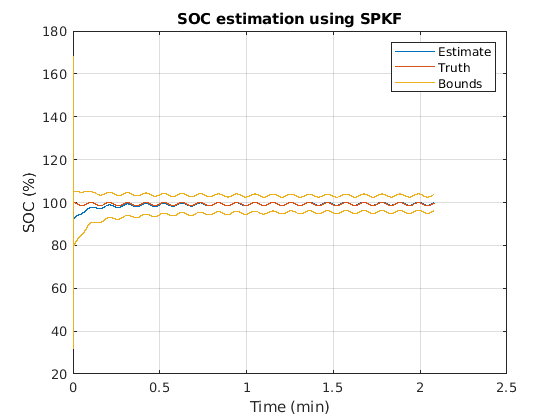


f1 = figure(1);clf;
plot(time/60,100*sochat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(sochat+socbound); NaN; 100*(sochat-socbound)]);
title('SOC estimation using SPKF'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');
hold off;

fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-sochat)).^2)));

RMS SOC estimation error = 1.09454%


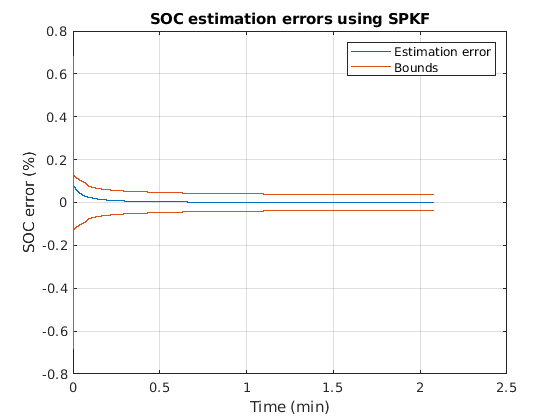

f2 = figure(2); clf;
plot(time/60,(soc-sochat)); hold on
plot([time/60; NaN; time/60],[socbound; NaN; -socbound]);
title('SOC estimation errors using SPKF');
xlabel('Time (min)'); ylabel('SOC error (%)'); 
legend('Estimation error','Bounds'); 
grid on;
hold off;


ind = find(abs(soc-sochat)>socbound);
fprintf('Percent of time error outside bounds = %g%%\n',length(ind)/length(soc)*100);

Percent of time error outside bounds = 0.00799936%



socbound = out.soc_bound.Data;
sochat = out.soc_hat.Data;
soc = out.soc.Data;
time = out.tout;

fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-sochat)).^2)));

RMS SOC estimation error = 3.19475%


ind = find(abs(soc-sochat)>socbound);
fprintf('Percent of time error outside bounds = %g%%\n',length(ind)/length(soc)*100);

Percent of time error outside bounds = 0%


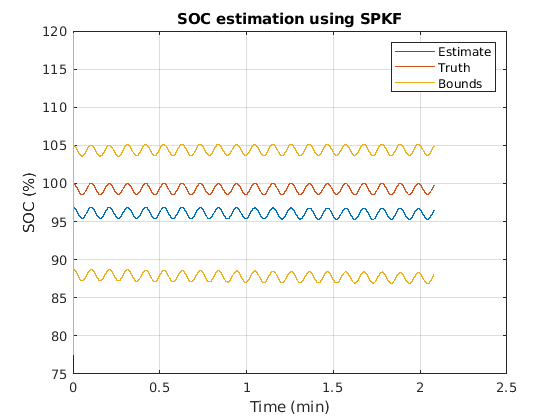



f3 = figure(3);clf;
plot(time/60,100*sochat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(sochat+socbound); NaN; 100*(sochat-socbound)]);
title('SOC estimation using SPKF'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');
hold off;

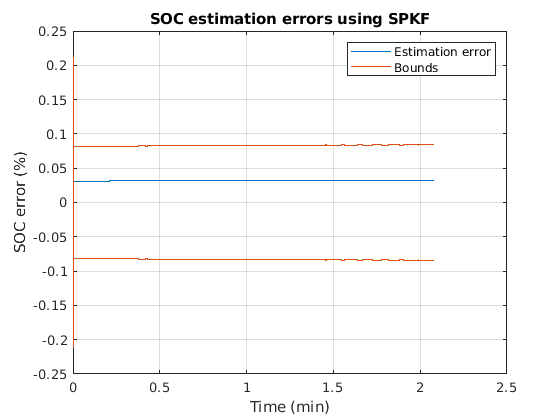


f4 = figure(4); clf;
plot(time/60,(soc-sochat)); hold on
plot([time/60; NaN; time/60],[socbound; NaN; -socbound]);
title('SOC estimation errors using SPKF');
xlabel('Time (min)'); ylabel('SOC error (%)'); 
legend('Estimation error','Bounds'); 
grid on;
hold off;

function spkfData = initSPKF(v0,SigmaX0,SigmaV,SigmaW,model)

  % Initial state description
  ir0   = 0;                           spkfData.irInd = 1;
  hk0   = 0;                           spkfData.hkInd = 2;
  SOC0  = getSOC(v0,model);            spkfData.zkInd = 3;
  spkfData.xhat  = [ir0 hk0 SOC0]'; % initial state
  % Covariance values
  spkfData.SigmaX = SigmaX0;
  spkfData.SigmaV = SigmaV;
  spkfData.SigmaW = SigmaW;
  spkfData.Snoise = real(chol(diag([SigmaW; SigmaV]),'lower'));
  spkfData.Qbump = 5;
  
  % SPKF specific parameters
  Nx = length(spkfData.xhat); spkfData.Nx = Nx; % state-vector length
  Ny = 1; spkfData.Ny = Ny; % measurement-vector length
  Nu = 1; spkfData.Nu = Nu; % input-vector length
  Nw = size(SigmaW,1); spkfData.Nw = Nw; % process-noise-vector length
  Nv = size(SigmaV,1); spkfData.Nv = Nv; % sensor-noise-vector length
  Na = Nx+Nw+Nv; spkfData.Na = Na;     % augmented-state-vector length
  
  h = sqrt(3); h = 3;
  spkfData.h = h; % SPKF/CDKF tuning factor  
  Weight1 = (h*h-Na)/(h*h); % weighting factors when computing mean
  Weight2 = 1/(2*h*h);      % and covariance
  spkfData.Wm = [Weight1; Weight2*ones(2*Na,1)]; % mean
  spkfData.Wc = spkfData.Wm;                     % covar

  % previous value of current
  spkfData.priorI = 0;
  spkfData.signIk = 0;
  
  % store model data structure too
  spkfData.model = model;
end  


function [zk,zkbnd,spkfData] = iterSPKF(vk,ik,deltat,spkfData)
    battery = spkfData.model;

    dt = .01;
 %parameters
    n = battery.n;
    eta = n;
    Q = battery.Q;
    G = battery.G;
    M0 = battery.M0;
    M = battery.M;
    R0 = battery.R0;
    R = battery.R;
    RC = exp(-dt/abs(battery.RC))';
   
    if ik<0, ik=ik*eta; end;
  
  % Get data stored in spkfData structure
  I = ik; %spkfData.priorI;
  SigmaX = spkfData.SigmaX;
  xhat = spkfData.xhat;
  Nx = spkfData.Nx;
  Nw = spkfData.Nw;
  Nv = spkfData.Nv;
  Na = spkfData.Na;
  Snoise = spkfData.Snoise;
  Wc = spkfData.Wc;
  irInd = spkfData.irInd;
  hkInd = spkfData.hkInd;
  zkInd = spkfData.zkInd;
  if abs(ik)>Q/100, spkfData.signIk = sign(ik); end;
  signIk = sign(ik);% spkfData.signIk;
  
  % Step 1a: State estimate time update
  %          - Create xhatminus augmented SigmaX points
  %          - Extract xhatminus state SigmaX points
  %          - Compute weighted average xhatminus(k)

  % Step 1a-1: Create augmented SigmaX and xhat
  [sigmaXa,p] = chol(SigmaX,'lower'); 
  if p>0,
    fprintf('Cholesky error.  Recovering...\n');
    theAbsDiag = abs(diag(SigmaX));
    sigmaXa = diag(max(SQRT(theAbsDiag),SQRT(spkfData.SigmaW)));
  end

  sigmaXa=[real(sigmaXa) zeros([Nx Nw+Nv]); zeros([Nw+Nv Nx]) Snoise];
  xhata = [xhat; zeros([Nw+Nv 1])];
  % NOTE: sigmaXa is lower-triangular

  % Step 1a-2: Calculate SigmaX points (strange indexing of xhata to 
  % avoid "repmat" call, which is very inefficient in MATLAB)
  Xa = xhata(:,ones([1 2*Na+1])) + ...
       spkfData.h*[zeros([Na 1]), sigmaXa, -sigmaXa];

  % Step 1a-3: Time update from last iteration until now
  %     stateEqn(xold,current,xnoise)
  Xx = stateEqn(Xa(1:Nx,:),I,Xa(Nx+1:Nx+Nw,:)); 
  xhat = Xx*spkfData.Wm;

  % Step 1b: Error covariance time update
  %          - Compute weighted covariance sigmaminus(k)
  %            (strange indexing of xhat to avoid "repmat" call)
  Xs = Xx - xhat(:,ones([1 2*Na+1]));
  SigmaX = Xs*diag(Wc)*Xs';
  
  % Step 1c: Output estimate
  %          - Compute weighted output estimate yhat(k)
  I = ik; yk = vk;
  Y = outputEqn(Xx,I,Xa(Nx+Nw+1:end,:),battery);
  yhat = Y*spkfData.Wm;

  % Step 2a: Estimator gain matrix
  Ys = Y - yhat(:,ones([1 2*Na+1]));
  SigmaXY = Xs*diag(Wc)*Ys';
  SigmaY = Ys*diag(Wc)*Ys';
  L = SigmaXY/SigmaY; 

  % Step 2b: State estimate measurement update
  r = yk - yhat; % residual.  Use to check for sensor errors...
  if r^2 > 100*SigmaY, L(:,1)=0.0; end 
  xhat = xhat + L*r; 
  xhat(zkInd)=min(1.05,max(-0.05,xhat(zkInd)));
  xhat(hkInd) = min(1,max(-1,xhat(hkInd)));

  % Step 2c: Error covariance measurement update
  SigmaX = SigmaX - L*SigmaY*L';
  [~,S,V] = svd(SigmaX);
  HH = V*S*V';
  SigmaX = (SigmaX + SigmaX' + HH + HH')/4; % Help maintain robustness
  
  % Q-bump code
  if r^2>4*SigmaY, % bad voltage estimate by 2-SigmaX, bump Q 
    fprintf('Bumping sigmax\n');
    SigmaX(zkInd,zkInd) = SigmaX(zkInd,zkInd)*spkfData.Qbump;
  end
  
  % Save data in spkfData structure for next time...
  spkfData.SigmaX = SigmaX;
  spkfData.xhat = xhat;
  zk = xhat(zkInd);
  zkbnd = 3*sqrt(SigmaX(zkInd,zkInd));

% Calculate new states for all of the old state vectors in xold.  
  function xnew = stateEqn(xold,current,xnoise)
    current = current + xnoise; % noise adds to current
    xnew = 0*xold;
    xnew(irInd,:) = RC*xold(irInd,:) + (1-diag(RC))*current;
    Ah = exp(-abs(current*G*deltat/(3600*Q)));  % hysteresis factor
    xnew(hkInd,:) = Ah.*xold(hkInd,:) + (Ah-1).*sign(current);
    xnew(zkInd,:) = xold(zkInd,:) - current/3600/Q;
    xnew(hkInd,:) = min(1,max(-1,xnew(hkInd,:)));
    xnew(zkInd,:) = min(1.05,max(-0.05,xnew(zkInd,:)));
  end

  % Calculate cell output voltage for all of state vectors in xhat
  function yhat = outputEqn(xhat,current,ynoise,model)
    yhat = getOCV_UKF(xhat(zkInd,:),model);
    yhat = yhat + M*xhat(hkInd,:) + M0*signIk;
    yhat = yhat - R*xhat(irInd,:) - R0*current + ynoise(1,:);
  end

  % "Safe" square root
  function X = SQRT(x)
    X = sqrt(max(0,x));
  end
end





